%   PID Calibration Script for Motor Speed Control
%   Author: Vignesh Babu A.


%Runtime Calibration of Kp, Ki, Kd
Kp= 106.2;
Ki=130;
Kd=11;
simulationOutput = sim('B_MotorSpeed_Task3');


%-----Extraction of Simulation data-----
format long;
simulationOutputSignals = simulationOutput.yout;
input = simulationOutputSignals{1};
output= simulationOutputSignals{2};

outputTimeData= simulationOutputSignals{2}.Values.time;
outputSignalData= simulationOutputSignals{2}.Values.Data;

%-------Overshoot check---------
currentFinalInputValue = input.Values.Data(end)

currentFinalInputValue =    100


OvershootAcceptablePercentage=0.05;
for i = output.Values.Data'
    if(i >currentFinalInputValue+(currentFinalInputValue*OvershootAcceptablePercentage))
        OverShootStatus = "True";
        break
    else
        OverShootStatus="False";
        continue
    end
end
OverShootPercentage = overshoot(outputSignalData,outputTimeData);

%------SteadyStateErrorCheck--------
currentFinalOutputValue = output.Values.Data(end)

currentFinalOutputValue =   99.999999999984908


finalValueOfInput = single(input.Values.Data(end));

if(currentFinalOutputValue == finalValueOfInput)
    SteadyStateError='False';
else
    SteadyStateError="True";
end
SteadyStatePercentage = (finalValueOfInput-currentFinalOutputValue)/finalValueOfInput;


%-----Rise Time Calculation----
RiseTime= risetime(outputSignalData,outputTimeData);


%-----------Report-------------
fprintf("Test Result:\n" + ...
    "Kp = %f\n" + ...
    "ki = %f\n" + ...
    "Kd = %f\n" + ...
    "Overshoot Beyond Acceptable Percentage = %s\n" + ...
    "Overshoot percentage = %f %%\n" + ...
    "Output value at simulation stop time = %f\n" + ...
    "Steady state error percentage = ~ %f %% \n" + ...
    "Approx. Rise Time = %f seconds\n",Kp, Ki, Kd, OverShootStatus,OverShootPercentage,currentFinalOutputValue,SteadyStatePercentage,RiseTime);

Test Result:
Kp = 106.200000
ki = 130.000000
Kd = 11.000000
Overshoot Beyond Acceptable Percentage = False
Overshoot percentage = -0.883177 %
Output value at simulation stop time = 100.000000
Steady state error percentage = ~ 0.000000 % 
Approx. Rise Time = 0.101427 seconds


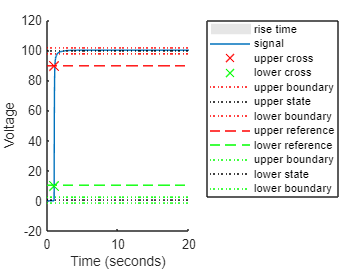


%----Plotting Output Signal------
risetime(outputSignalData,outputTimeData);
hold on
ylabel('Voltage');
hold off

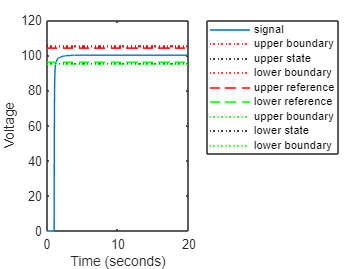

finalValueOfInput= double(finalValueOfInput);
overshoot(outputSignalData,outputTimeData,'StateLevels',[finalValueOfInput-finalValueOfInput*OvershootAcceptablePercentage,finalValueOfInput+finalValueOfInput*OvershootAcceptablePercentage]);
hold on
ylabel('Voltage');
hold off



%----------End--------



